# Fit one excitation spectrum

init;
% Author: Abbas El Moussawi
% COPYRIGHT 2024: EMPI-RF - University of Duisburg-Essen  

### Species

species = availableSpecies(1);


### Measurement



measPath = "input-data\exampleSpectra\NO.meassurement.xlsx";
measUnit = '1/cm';

unit = '1/cm';
[wnSpec, nmSpec] = loadSpectrum(measPath, measUnit);

excWnum = wnSpec.wnum;
plotWnum = excWnum;

measSpec = wnSpec.intens;

plotSpec = measSpec;

simWnum  = linspace(min(excWnum), max(excWnum), length(excWnum))';

#### Initial fit parameters

b = zeros(7,1);
T = 1600; b(1) = 50;% %
dnuGL = 0.5; b(2) = 0.7; % 1/cm 
dnuLL = 0.11; b(3) = 0.5;% 1/cm 
scale = 1; b(4) = 15;% %

bScPer = b(4);
b(4) = b(4)*scale/100;
mxSpec = max(measSpec);
if (scale- b(4)) > mxSpec || (scale+ b(4)) < mxSpec
    fprintf(['The given scale, %.2f, is far from max of spectrum %.2f.\n' ...
        'Reseting scale to %.2f.\n'], scale,mxSpec, mxSpec)
    scale = mxSpec;
    b(4) =bScPer*scale/100;
    clear scLo scUp a
end
clear mxSpec bScPer

If collissions are set, the collisional shift is added to this value:

dnuSh = 0.1; b(5) = 0.2;% 1/cm 
offset = 0.1; b(6) = 0.6;% -
slope = 0; b(7) = 0.001;% -

bLo = [
    T      - T*b(1)/100 ,...%
    dnuGL  - b(2),... %
    dnuLL  - b(3),... %
    scale  - b(4),... %
    dnuSh  - b(5),... %
    offset - b(6) ,... %
    slope  - b(7) %
    ];
if bLo(2) <=0
    bLo(2) = 0.001;
end
if bLo(3) <=0
    bLo(3) = 0.001;
end
if bLo(4) <=0
    bLo(4) = 0.001;
end

bUp = [
    T      + T*b(1)/100 ,...%
    dnuGL  + b(2),... %
    dnuLL  + b(3),... %
    scale  + b(4),... %
    dnuSh  + b(5),... %
    offset + b(6) ,... %
    slope  + b(7) %
    ];


#### **Pressure and collisions data**

*(Support for NO, otherwise update function 'collissions')*


P = 0.03;

dnuL = 0.01;
dnuShC = 0;

unit = lower(unit);

if strcmpi(unit,'nm')
    plotWnum = nmSpec.wnum;
    plotSpec = nmSpec.intens;
    dnuGL = convWnumWlen(dnuGL,simWnum(end));
    dnuLL = convWnumWlen(dnuLL, simWnum(end));
    dnuSh = convWnumWlen(dnuSh, simWnum(end));
end

[linelist, Z, n,~,MM, emList] = selectLines(species,simWnum );

if n == 0
    warning("No lines found.")
    return;
end

colls =  collisions(species);

if ~isempty(colls)
    path = "D:\Cloud\OneDrive - Universitaet Duisburg-Essen\06_dev\git\LIFSim4.0\input-data\gas-compositions\air+NO.csv";
    gas = loadGasComposition(path);
    [dnuL, dnuShC] = collisionalBroadening(gas, colls, P, T);
    [quen,linelist] = quenchRate(gas, colls, T,P, MM, linelist);
end

#### **Detection filter**

*    Keep empty to ignore filter*

pathFilter = "D:\Cloud\OneDrive - Universitaet Duisburg-Essen\06_dev\git\LIFSim4.0\input-data\filters\no.Notch.20deg.csv";
filterUnit = 'nm';
filter = 0;
nmFilter = 0;
if isfile(pathFilter)
    [filter, nmFilter] = loadSpectrum(pathFilter,filterUnit);
    [linelist,emList] = fluorTransm(linelist, emList, filter);
end


#### Preview spectrum with initial parameters

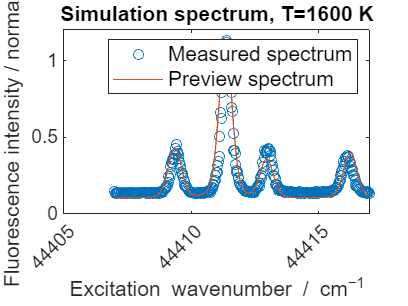

 

startParams = [
    T,    ...  %T
    dnuGL,...  %dnuGL
    dnuLL,...  %dnuLL
    scale,...  %scale
    dnuSh,...  %shift
    offset,... %offset
    slope% baseline slope
    ];


prefit = excitationSpecSolution(simWnum, linelist, MM, startParams, Z= Z, colls=colls, gas=gas, P=P);

lineShifting = true;
lineFitRegions =  [44415 44417] ;

figure;
plot(plotWnum, plotSpec, 'o', DisplayName='Measured spectrum')

title(['Simulation spectrum, T=' num2str(startParams(1)) ' K'])
hold on;

plotSimWnum = simWnum;
if strcmpi(unit,'nm')
    plotSimWnum = convWnumWlen(plotSimWnum);
    prefit = flipud(prefit);
end


plot(plotSimWnum, prefit, DisplayName='Preview spectrum' )
legend;
LABELS(unit);
LABELS("flourIntNorm");

drawnow;


#### Fitting

verbose = true;

 
options = getFitOptions(id="lsqnonlin");

if ~verbose
    options.Display = "none";
end

bestFit = startParams;

if lineShifting

    [bestFit, residue1]  =  fitExcitationSpec(simWnum, measSpec, linelist, MM, startParams,  options, lb=bLo, ub=bUp,Z=Z, colls=colls, gas=gas, P=P);
    
    linelist = linesShiftCorrection(...
        linelist, simWnum, measSpec, bestFit, MM, Z=Z, colls=colls, gas=gas, P=P,...
        fitRegions = lineFitRegions, verbose = verbose, boundary=0.2);
    
end


Optimization stopped because the relative sum of squares (r) is changing
by less than options.FunctionTolerance = 1.000000e-05.




Optimization stopped because the relative sum of squares (r) is changing
by less than options.FunctionTolerance = 1.000000e-05.

6. 
Shifted Q12, delta: 44416.0742 - 44415.993 = 0.081207
7. 
Shifted P2, delta: 44416.1758 - 44415.9974 = 0.1784
Residue: 0.10466


[bestFit, residue] = fitExcitationSpec(simWnum, measSpec, linelist, MM, bestFit,  options,lb=bLo, ub=bUp,Z=Z, colls=colls, gas=gas, P=P);


Optimization stopped because the relative sum of squares (r) is changing
by less than options.FunctionTolerance = 1.000000e-05.




disp(['Residue: ' num2str(residue)])

Residue: 0.097127


[fitSpec, collEffect] = excitationSpecSolution(simWnum, linelist, MM, bestFit, Z= Z, colls=colls, gas=gas, P=P);

disp(fitParamStr(bestFit))

1. T: 1407.09 K
2. dnuGL: 0.37 1/cm
3. dnuLL:0.04 1/cm
4. Scale:0.97
5. dnuSh:0.14 1/cm
6. Offset:0.13
7. Slope:0


if ~isempty(colls)
    disp('Collision effects:')
    disp(['dnuShC: ' num2str(collEffect.dnuShC) ' 1/cm'])
    disp(['dnuL: ' num2str(collEffect.dnuL) ' 1/cm'])
end

Collision effects:


dnuShC: -0.0022246 1/cm


dnuL: 0.0054725 1/cm


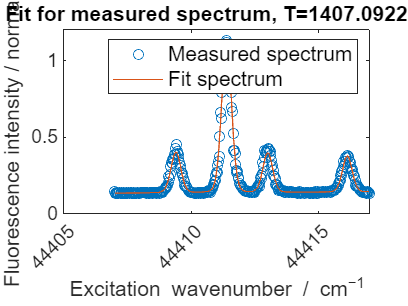


figure, plot(plotWnum, plotSpec, 'o', DisplayName='Measured spectrum')
title(['Fit for measured spectrum, T=' num2str(bestFit(1)) ' K'])
hold on;

if strcmpi(unit,'nm')
    fitSpec = fliplr(fitSpec);
end
plot(plotSimWnum, fitSpec, DisplayName='Fit spectrum')

legend;
LABELS(unit);
LABELS("flourIntNorm");

drawnow;

